# Second Partial Examination - Design of a Controller 

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure

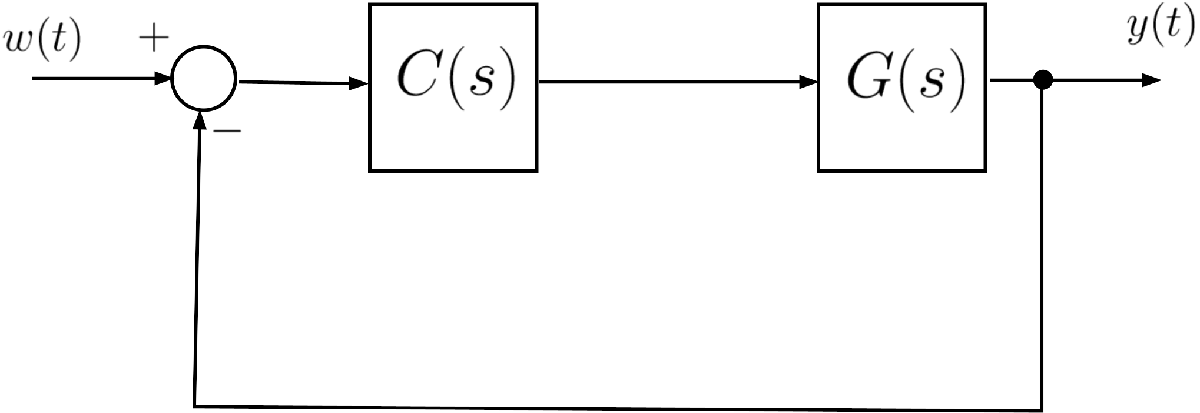	

where $G(s)$ is given by                


$$G(s) = \frac{4.8\,\left(1+0.01\,s\right)}{(1+0.25\,s)\,(1-25\,s)}$$


## **Question**		

**Q1**: Design a controller $C(s)$ such that all following requirements are simultaneously met: 

- The crossover angular frequency satisfies $\omega_c \ge 4.0\;\text{rad/s}$; 

- The phase margin satisfies $\varphi_m \ge 40^{\degree}$.

- $\left| e(\infty)\right| =0$ for $w(t) =  \mathbf{1}(t)$, where $\mathbf{1}(t)$ denotes the unit step function.

**ANALISI PRELIMINARE**

Noto subito che il sitema non è stabile ad anello chiuso quindi dovrò cambiare l'architettura del sistema aggiungendo un controllore $C_1$ per stabilizzare il sistema in anello chiuso ed un controllore $C_2$per soddisfare gli altri requisiti requisiti 

**PROGETTO CONTROLLORE **$C_1$

Considero una struttura a doppio anello e considero $C_1 \left(s\right)=\mu_1 \left(1+0\ldotp 25*s\right)$. Ricordo che sia $L_1 =C_1 \left(s\right)\cdot G\left(s\right)=\frac{{4\ldotp 8\mu }_1 \left(1+0\ldotp 001s\right)}{\left(1-25s\right)}$  quindi $F_1 \left(s\right)=\frac{L_1 \left(s\right)}{1+L_1 \left(s\right)}=$$\frac{{4\ldotp 8\mu }_1 \left(1+0\ldotp 01s\right)}{\left(1-25s\right)+\mu_1 }$ quindi se $\mu_1 =-26$ allora ho che $F_1 \left(s\right)=$$\frac{4\ldotp 8\cdot \left(26\right)\left(1+0\ldotp 01s\right)}{25*\left(1+s\right)}$ che è un sistema stabile ad anello chiuso

**PROGETTO CONTROLLORE **$C_2$

Prima di tutto inserisco un polo nell'origine per verificare l'ipotesi sul guadagno statico e successivamente controllo che gli altri requisiti non siano già rispettati così:

$C_2 =\frac{\mu_2 }{s}$ con mu2 molto piccolo per avere un buon margine di fase

s=tf('s');
Fs=(26*4.8)*(1+0.01*s)/(25*(1+s));
C2s=(0.001)/(s);
T = feedback(C2s * Fs, 1);

stepinfo(T)

ans = struct with fields:
         RiseTime: 437.9329
    TransientTime: 780.7750
     SettlingTime: 780.7750
      SettlingMin: 0.9040
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 1.4595e+03


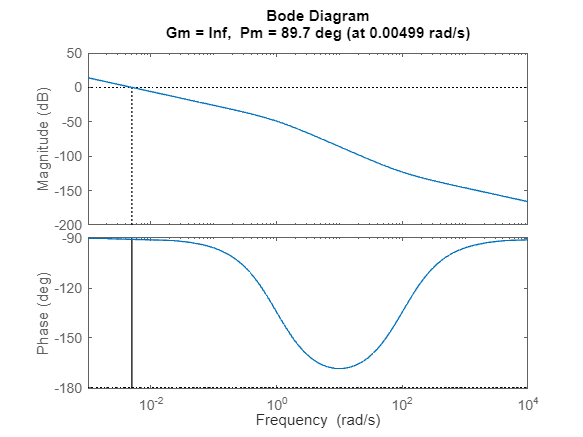

margin(C2s * Fs)

il margine di fase è rispettato.

controlSystemDesigner(Fs, C2s)
